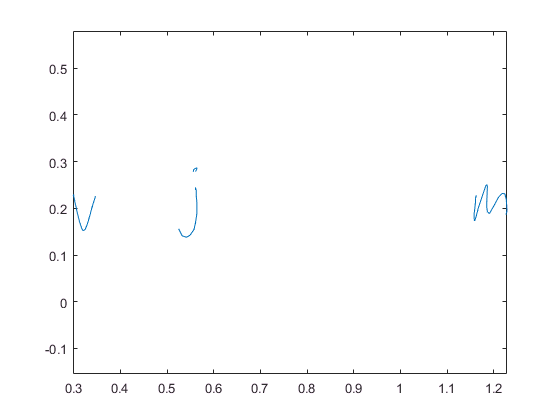

%Let X and Y be the coordinates to show the position and ID of a particular sensor
%Let P be the data transfer speed or rate per each coordinate 
%The faults have been classified into 3 categories
%RED,BLUE and GREEN to show the degree of failure
%##WE USE THE TIME TAKEN FOR THE DATA ACQUISITION FROM THE SENSOR
%## AS WELL AS THE ACCURACY OF THE RESULTS GIVEN TWO SENSORS PLACED ON VERY CLOSE COORDINATES OR SAME PLACE

%Import and process the data for Sensor J
letter=readtable('J.txt'); %J is a data table generated from the the sensors output Data
letter.X = 1.5*letter.X;
letter.Time = (letter.Time - letter.Time(1))/1000;
plot(letter.X ,letter.Y);
axis equal;

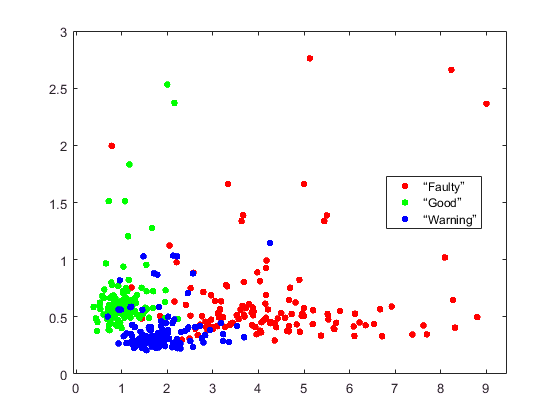

dur = letter.Time(end);
aratio = range(letter.Y)/range(letter.X);


%Plotting the features for the entire data
features=readtable('features.xlsx');
gscatter(features.AspectRatio,features.Duration,features.Character);